close all; clear all; clc;
%% === DEFINICIÓN DEL SISTEMA ===

% Parámetros físicos
Ks = 1.61;        % N/m
Jh = 0.0021;      % kg*m^2
Jl = 0.0059;      % kg*m^2
Kg = 70;          % sin unidades
Km = 0.00767;     % N*m/A
Rm = 2.6;         % ohm
g = -9.81;         % m/s^2
m = 0.403;        % kg
hcm = 0.06;      % m
% Variables simbólicas
syms x1 x2 x3 x4 u v real
x = [x1; x2; x3; x4];

% Dinámica no lineal

f1 = x3;
f2 = x4;
f3 = (Ks/Jh)*x2 - ((Km^2 * Kg^2)/(Rm*Jh))*x3;
f4 = -((Ks/Jh)+(Ks/Jl))*x2 + (Km^2 * Kg^2)/(Rm*Jh)*x3 ...
          + (m*g*hcm/Jl)*sin(x1 + x2);

f = [f1; f2; f3; f4];

% Vector g(x)
gvec = [0;
        0;
        (Km*Kg)/(Rm*Jh);
        -(Km*Kg)/(Rm*Jh)];

% Salida
h = x1 + x2;

%% === DERIVADAS DE LIE ===

% Derivadas de Lie
Lfh    = gradient(h, x).'*f;
Lf2h   = gradient(Lfh, x).'*f;
Lf3h   = gradient(Lf2h, x).'*f;
Lf4h   = gradient(Lf3h, x).'*f;

% Derivadas cruzadas con g
Lgh     = gradient(h, x).'*gvec

$$Lgh = 0$$

LgLfh   = gradient(Lfh, x).'*gvec

$$LgLfh = 0$$

LgLf2h  = gradient(Lf2h, x).'*gvec

$$LgLf2h = 0$$

LgLf3h  = gradient(Lf3h, x).'*gvec;
disp('Es distinto de 0 en la 4 derivada cruzada'); disp(LgLf3h);

Es distinto de 0 en la 4 derivada cruzada


$$\frac{1062128232431616355}{39582418599936}$$


%% === COORDENADAS LINEALIZADAS (DIFEOMORFISMO) ===

z1 = simplify(h)

$$z1 = x_{1}+x_{2}$$

z2 = simplify(Lfh) 

$$z2 = x_{3}+x_{4}$$

z3 = simplify(Lf2h)

$$z3 = -\frac{3600434686208869\,x_{2}}{13194139533312}-\frac{707282807527887\,\sin\left(x_{1}+x_{2}\right)}{17592186044416}$$

z4 = simplify(Lf3h)

$$z4 = -\frac{707282807527887\,x_{3}\,\cos\left(x_{1}+x_{2}\right)}{17592186044416}-x_{4}\,\left(\frac{707282807527887\,\cos\left(x_{1}+x_{2}\right)}{17592186044416}+\frac{3600434686208869}{13194139533312}\right)$$

%% === CÁLCULO DE LA ENTRADA u = α(x) + β(x)v ===

v=Lf4h+LgLf3h*u;
v=simplify(v)

$$v = \begin{array}{l} \frac{1062128232431616355\,u}{39582418599936}-\frac{707282807527887\,\cos\left(x_{1}+x_{2}\right)\,\left(\frac{2300\,x_{2}}{3}-\frac{3715129576983801\,x_{3}}{70368744177664}\right)}{17592186044416}+x_{3}\,\sigma_{1}+x_{4}\,\sigma_{1}+\left(\frac{707282807527887\,\cos\left(x_{1}+x_{2}\right)}{17592186044416}+\frac{3600434686208869}{13194139533312}\right)\,\left(\frac{4571980553916023\,x_{2}}{4398046511104}-\frac{3715129576983801\,x_{3}}{70368744177664}+\frac{707282807527887\,\sin\left(x_{1}+x_{2}\right)}{17592186044416}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{707282807527887\,x_{3}\,\sin\left(x_{1}+x_{2}\right)}{17592186044416}+\frac{707282807527887\,x_{4}\,\sin\left(x_{1}+x_{2}\right)}{17592186044416} \end{array}$$

Control linealizador


$$u=\frac{1}{L_gL_f^{3}h(x)}\left[-L_f^{4}h(x)+v\right]$$


clear v
syms v
u=1/LgLf3h*(v-Lf4h)

$$u = \begin{array}{l} \frac{39582418599936\,v}{1062128232431616355}+\frac{6365545267750983\,\cos\left(x_{1}+x_{2}\right)\,\left(\frac{2300\,x_{2}}{3}-\frac{3715129576983801\,x_{3}}{70368744177664}\right)}{4248512929726465420}-\frac{39582418599936\,x_{3}\,\sigma_{1}}{1062128232431616355}-\frac{39582418599936\,x_{4}\,\sigma_{1}}{1062128232431616355}-\frac{39582418599936\,\left(\frac{707282807527887\,\cos\left(x_{1}+x_{2}\right)}{17592186044416}+\frac{3600434686208869}{13194139533312}\right)\,\left(\frac{4571980553916023\,x_{2}}{4398046511104}-\frac{3715129576983801\,x_{3}}{70368744177664}+\frac{707282807527887\,\sin\left(x_{1}+x_{2}\right)}{17592186044416}\right)}{1062128232431616355}\\ \mathrm{where}\\ \sigma_{1}=\frac{707282807527887\,x_{3}\,\sin\left(x_{1}+x_{2}\right)}{17592186044416}+\frac{707282807527887\,x_{4}\,\sin\left(x_{1}+x_{2}\right)}{17592186044416} \end{array}$$

simplify(u)

$$ans = -\frac{6365545267750983\,\sin\left(x_{1}+x_{2}\right)\,{x_{3}}^{2}}{4248512929726465420}-\frac{6365545267750983\,\sin\left(x_{1}+x_{2}\right)\,x_{3}\,x_{4}}{2124256464863232710}+\frac{11145388730951403\,x_{3}}{20758779532410880}-\frac{6365545267750983\,\sin\left(x_{1}+x_{2}\right)\,{x_{4}}^{2}}{4248512929726465420}+\frac{39582418599936\,v}{1062128232431616355}-\frac{13715941661748069\,x_{2}}{1297423720775680}-\frac{2121848422583661\,\sin\left(x_{1}+x_{2}\right)}{5189694883102720}-\frac{2121848422583661\,x_{2}\,\cos\left(x_{1}+x_{2}\right)}{5189694883102720}-\frac{4502240728420770428006544162921\,\cos\left(x_{1}+x_{2}\right)\,\sin\left(x_{1}+x_{2}\right)}{74740629871854859077938808094720}$$


%% === DISEÑO DEL CONTROLADOR LINEALALIZADO POR FEEDBACK LINEARIZATION ===

Az = [0 1 0 0;
      0 0 1 0;
      0 0 0 1;
      0 0 0 0];

Bz = [0; 0; 0; 1];
Cz = [1 0 0 0];

% Verificar controlabilidad
Control = ctrb(Az, Bz);
disp('Rango de la matriz de controlabilidad:');

Rango de la matriz de controlabilidad:


disp(rank(Control));  % debe ser 4 para controlabilidad completa

     4



% Polos deseados
orden = 4;
wb = 10;
[~, den] = besself(orden, 1);
pBessel = roots(den);
pBessel = wb * pBessel;

Kz = acker(Az, Bz, pBessel);
disp('Ganancia sin integrador Kz =');

Ganancia sin integrador Kz =


disp(Kz);

   1.0e+04 *

    1.0000    0.3201    0.0439    0.0031




% %% === CONTROL CON INTEGRADOR ===
orden = 5;
wb = 10;
[~, den] = besself(orden, 1);
pBessel2 = roots(den);
pBessel2 = wb * pBessel2;


Aa = [Az zeros(4,1); Cz 0];
Ba = [Bz; 0];
Kzi = acker(Aa, Ba, pBessel2);
disp('Ganancia con integrador Kzi =');

Ganancia con integrador Kzi =


disp(Kzi);

   1.0e+05 *

    0.3936    0.0689    0.0068    0.0004    1.0000




%% === CONDICIONES INICIALES PARA SIMULINK ===

%% Punto de equilibrio (para yd = 0.5 rad)
yd = 0;  % Referencia deseada

% Calcular punto de equilibrio
syms v_sym
eq = yd == asin(-(Km*Kg)/(Rm*m*g*hcm)*v_sym);
v_val = double(vpasolve(eq, v_sym));

x3_eq = 0;
x4_eq = 0;
x2_eq = -(Km*Kg)/(Rm*Ks)*v_val;
theta = asin(-(Km*Kg)/(Rm*m*g*hcm)*v_val);
x1_eq = theta - x2_eq;

% x3_eq = 0;
% x4_eq = 0;
% x2_eq = 0;
% x1_eq = 0;

%% Variables para Simulink
% Puntos de equilibrio
x1_ss = x1_eq;
x2_ss = x2_eq;
x3_ss = x3_eq;
x4_ss = x4_eq;
% Condiciones iniciales (10% del punto de equilibrio)
cix1 = x1_eq;
cix2 = x2_eq;
% cix1 = 0;
% cix2 = 0
cix3 = 0;
cix4 = 0;

% Referencia
ref_step = yd;
pert=0.04;

% Ejecutar simulación
simOut = sim('SIMULINK_flexible_joint');

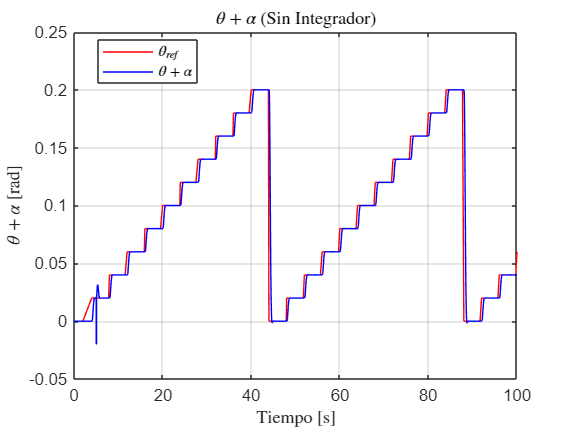


%% === SIN INTEGRADOR ===

% x1 + x2 vs referencia (Ángulo total del enlace largo)
figure('Name', 'Ángulo Total (Sin Integrador)');
plot(x1x2SI.time, x1x2SI.signals.values(:,1), 'r'); hold on; % Referencia
plot(x1x2SI.time, x1x2SI.signals.values(:,2), 'b');           % x1 + x2
grid on;
xlabel('Tiempo [s]', 'Interpreter', 'latex');
ylabel('$\theta + \alpha$ [rad]', 'Interpreter', 'latex');
legend('$\theta_{ref}$', '$\theta + \alpha$', 'Interpreter', 'latex', 'Location', 'best');
title('$\theta + \alpha$ (Sin Integrador)', 'Interpreter', 'latex');

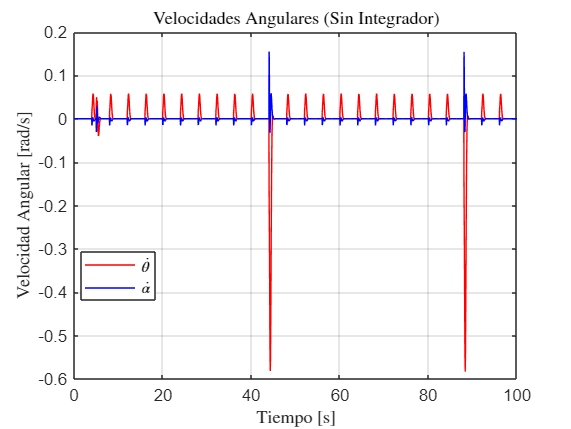


% x3 y x4 (Velocidades angulares)
figure('Name', 'Velocidades Angulares (Sin Integrador)');
x3_SI = x3x4SI.signals(1).values;  % θ'
x4_SI = x3x4SI.signals(2).values;  % α'
t_SI  = x3x4SI.time;

plot(t_SI, x3_SI, 'r'); hold on;
plot(t_SI, x4_SI, 'b');
grid on;
xlabel('Tiempo [s]', 'Interpreter', 'latex');
ylabel('Velocidad Angular [rad/s]', 'Interpreter', 'latex');
legend('$\dot{\theta}$', '$\dot{\alpha}$' , 'Interpreter', 'latex', 'Location', 'best');
title('Velocidades Angulares (Sin Integrador)', 'Interpreter', 'latex');

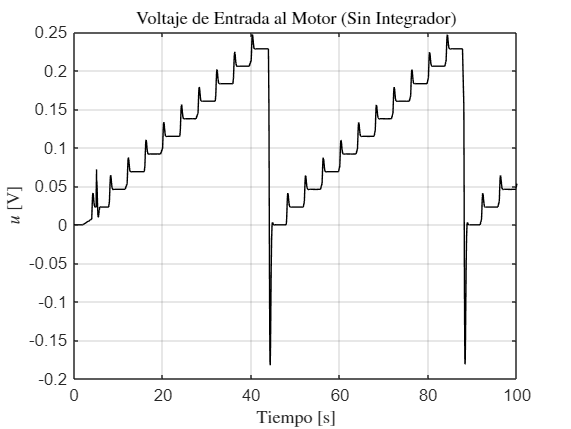


% Señal de control
figure('Name', 'Señal de Control (Sin Integrador)');
plot(SenalControlSI.time, SenalControlSI.signals.values, 'k');
grid on;
xlabel('Tiempo [s]', 'Interpreter', 'latex');
ylabel('$u$ [V]', 'Interpreter', 'latex');
title('Voltaje de Entrada al Motor (Sin Integrador)', 'Interpreter', 'latex');

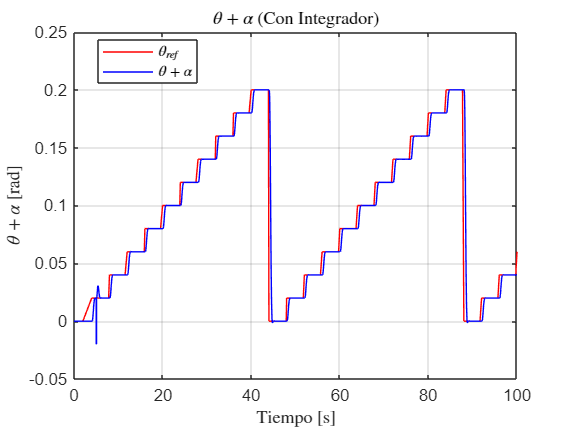


%% === CON INTEGRADOR ===

% x1 + x2 vs referencia
figure('Name', 'Ángulo Total (Con Integrador)');
plot(x1x2CI.time, x1x2CI.signals.values(:,1), 'r'); hold on; % Referencia
plot(x1x2CI.time, x1x2CI.signals.values(:,2), 'b');           % x1 + x2
grid on;
xlabel('Tiempo [s]', 'Interpreter', 'latex');
ylabel('$\theta + \alpha$ [rad]', 'Interpreter', 'latex');
legend('$\theta_{ref}$', '$\theta + \alpha$', 'Interpreter', 'latex', 'Location', 'best');
title('$\theta + \alpha$ (Con Integrador)', 'Interpreter', 'latex');

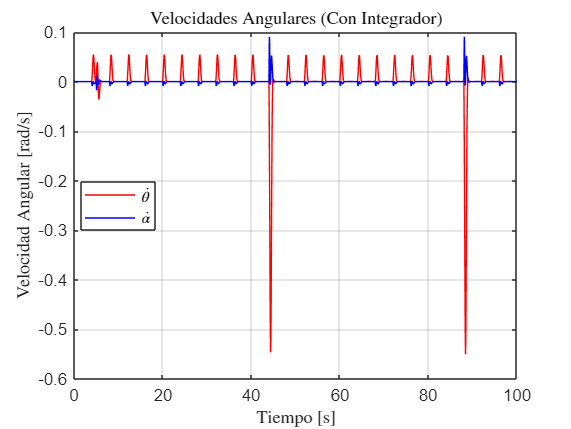


% x3 y x4 (Velocidades angulares)
figure('Name', 'Velocidades Angulares (Con Integrador)');
x3_CI = x3x4CI.signals(1).values;
x4_CI = x3x4CI.signals(2).values;
t_CI  = x3x4CI.time;

plot(t_CI, x3_CI, 'r'); hold on;
plot(t_CI, x4_CI, 'b');
grid on;
xlabel('Tiempo [s]', 'Interpreter', 'latex');
ylabel('Velocidad Angular [rad/s]', 'Interpreter', 'latex');
legend('$\dot{\theta}$', '$\dot{\alpha}$' , 'Interpreter', 'latex', 'Location', 'best');
title('Velocidades Angulares (Con Integrador)', 'Interpreter', 'latex');

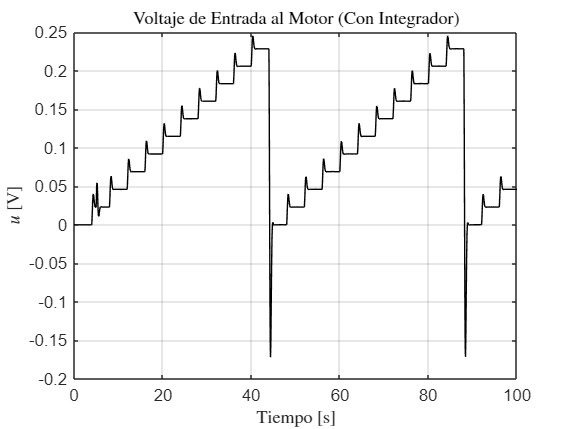


% Señal de control
figure('Name', 'Señal de Control (Con Integrador)');
plot(SenalControlCI.time, SenalControlCI.signals.values, 'k');
grid on;
xlabel('Tiempo [s]', 'Interpreter', 'latex');
ylabel('$u$ [V]', 'Interpreter', 'latex');
title('Voltaje de Entrada al Motor (Con Integrador)', 'Interpreter', 'latex');


% === CÁLCULO DEL ITAE ===

% Sin integrador
t_SI = x1x2SI.time;
ref_SI = x1x2SI.signals.values(:,1);
y_SI   = x1x2SI.signals.values(:,2);
e_SI   = abs(ref_SI - y_SI);
ITAE_SI = trapz(t_SI, t_SI .* e_SI);

% Con integrador
t_CI = x1x2CI.time;
ref_CI = x1x2CI.signals.values(:,1);
y_CI   = x1x2CI.signals.values(:,2);
e_CI   = abs(ref_CI - y_CI);
ITAE_CI = trapz(t_CI, t_CI .* e_CI);

% Mostrar resultados
fprintf('ITAE sin integrador: %.4f\n', ITAE_SI);

ITAE sin integrador: 22.3043


fprintf('ITAE con integrador: %.4f\n', ITAE_CI);

ITAE con integrador: 25.8191


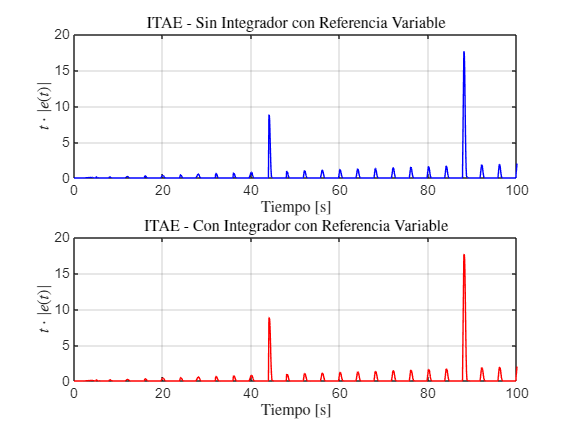


% === GRÁFICA DEL PRODUCTO t * |e(t)| ===

figure('Name', 'ITAE - Producto t * |e(t)|');

% Sin integrador
subplot(2,1,1);
plot(t_SI, t_SI .* e_SI, 'b');
grid on;
xlabel('Tiempo [s]', 'Interpreter', 'latex');
ylabel('$t \cdot |e(t)|$', 'Interpreter', 'latex');
title('ITAE - Sin Integrador con Referencia Variable', 'Interpreter', 'latex');

% Con integrador
subplot(2,1,2);
plot(t_CI, t_CI .* e_CI, 'r');
grid on;
xlabel('Tiempo [s]', 'Interpreter', 'latex');
ylabel('$t \cdot |e(t)|$', 'Interpreter', 'latex');
title('ITAE - Con Integrador con Referencia Variable', 'Interpreter', 'latex');